Data_location = "../Datasets/EngineFaultDB_Final.xlsx";
data = readtable(Data_location, 'VariableNamingRule', 'preserve');

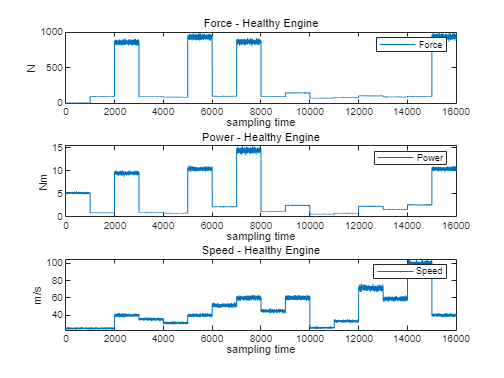

figure();
t = 1:16000;
Force = table2array(data(1:16000, 4));
Power = table2array(data(1:16000, 5));
Speed = table2array(data(1:16000, 9));

hold on;
subplot(3,1,1);
plot(t, Force);
title("Force - Healthy Engine");
ylabel("N");
xlabel("sampling time");
legend("Force")

subplot(3,1,2);
plot(t, Power);
title("Power - Healthy Engine");
ylabel("Nm");
xlabel("sampling time");
legend("Power")

subplot(3,1,3);
plot(t, Speed);
title("Speed - Healthy Engine");
ylabel("m/s");
xlabel("sampling time");
legend("Speed")

hold off;

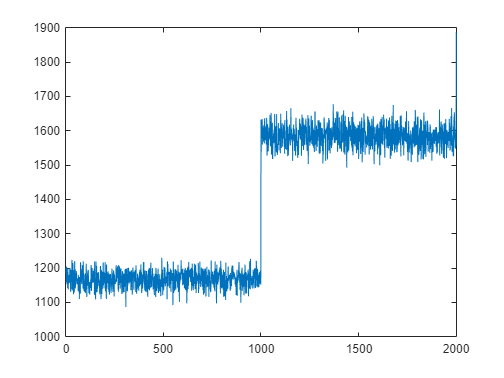

t_2=1:2000;
RPM_fault1 = table2array(data(16001:16001+1999, 6));
plot(t_2,RPM_fault1);